# MAT-63506 Scientific computing, Solutions for exercise set 4,

# Mar 26 - April 1, 2018

## Exercise 1

Form the `X` and `Y` matrices with `meshgrid` and compute the function values on the grid. We use elementwise operations since `X`, `Y` are matrices.

[X, Y] = meshgrid(linspace(-3.5, 3.5, 200));
Z = sin(2*X.^2 + Y.^2 + 2) + cos(X.^2 + 3*Y.^2 + 3);

Surface plot.

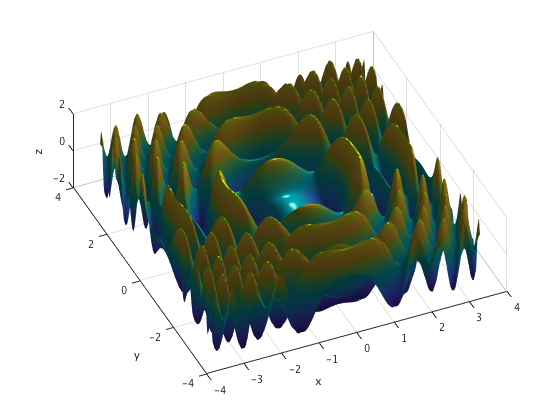

surf(X, Y, Z)
colormap default
shading interp
hl = light;
view([-24, 70])
xlabel('x'), ylabel('y'), zlabel('z')

Contour plot

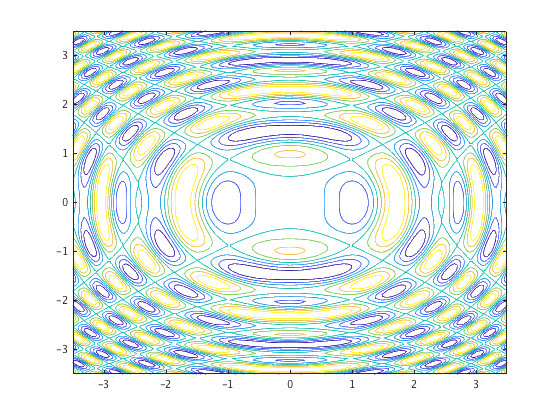

contour(X, Y, Z)

## Exercise 2

Form the grid in the `uv`-parameter plane, compute the `x`, `y`, and `z` coordinates on the grid, and plot the surface.

h =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [41×6284 double]
           YData: [41×6284 double]
           ZData: [41×6284 double]
           CData: [41×6284 double]

  Show all properties


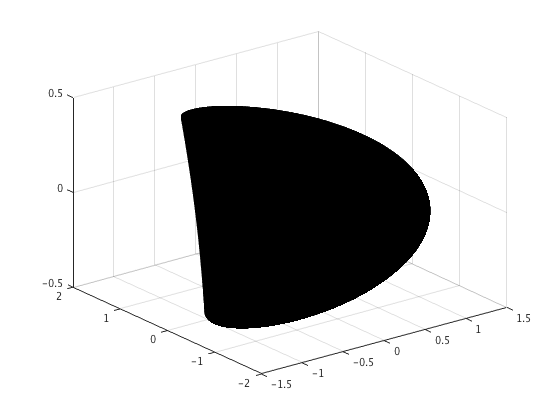

u = 0:0.001:2*pi; v = -1:0.05:1;
[U, V] = meshgrid(u, v);

TMP = 1 + V.*cos(U/2)/2;
X = TMP.*cos(U);
Y = TMP.*sin(U);
Z = V.*sin(U/2)/2;

h = surf(X, Y, Z)

The meshlines are so close to one another that the surface looks black. We fix this by changing the  shading, lightangle, material, and view.

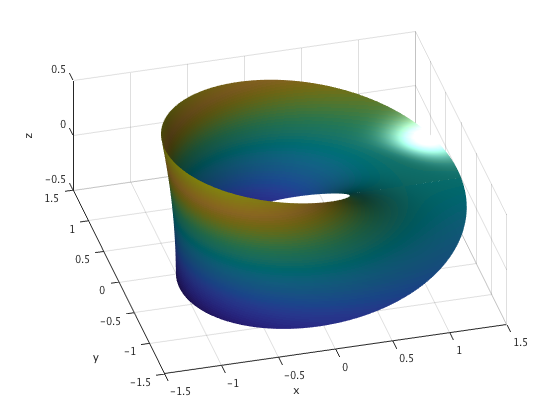

set(h, 'FaceColor', 'interp', 'EdgeColor','none', 'FaceLighting','gouraud')
lightangle(-45, 50)
material metal
view([-15, 60])
xlabel('x'); ylabel('y'); zlabel('z');

## Exercise 3

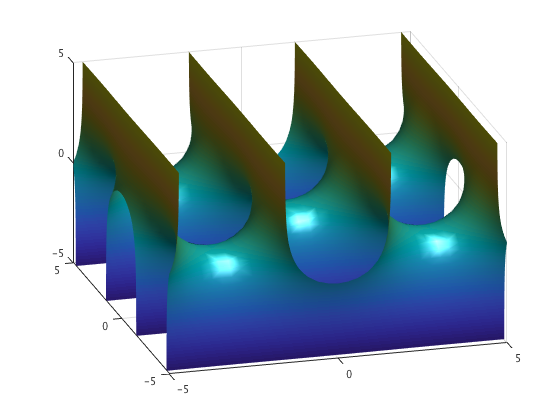

fimplicit3(@(x,y,z) exp(z).*cos(x) - cos(y), [-5 5], 'EdgeColor','none')
shading interp
camlight
view([-15.90 30.00])

## Exercise 4

Make the grid and compute the function values on it.

[X, Y] = meshgrid(linspace(-2, 2, 500));
Z = X + 1i*Y;
F = (Z - 2)./(Z.^2 + Z + 2);

Plot $\ln(|f(z)|)$ using $\arg f(z)$ as the coloring function.

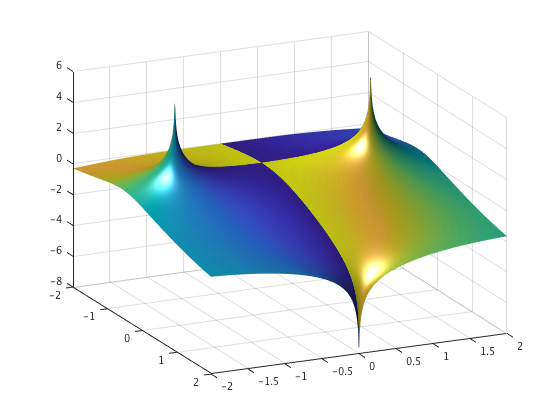

surf(X, Y, log(abs(F)), angle(F))
shading interp
camlight
view([65 24])

## Exercise 5

First we give the version that uses the `WindowButtonDownFcn` method.

Plot the first point, set `h` to a handle to the plot and get handles to current window and axis.

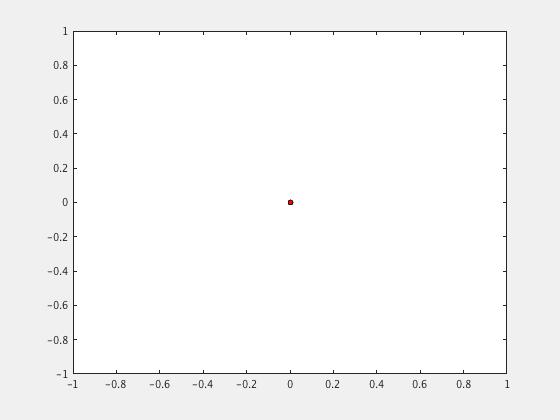

figure('Visible', 'on')
x = [0 0];
h = plot(x(1), x(2), 'o', 'MarkerSize', 5,...
	'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'k');


hf = gcf; % Handle to current window
ha = gca; % Handle to current axes

Set `UserData` of the figure to `true` and `WindowButtonDownFcn` to a callback function that sets `UserData` to `false` when the user clicks anywhere in the figure window.

hf.UserData = true;
hf.WindowButtonDownFcn = ...
    @(hObject, event) set(hObject, 'UserData', false);

Add static text fields to the window.

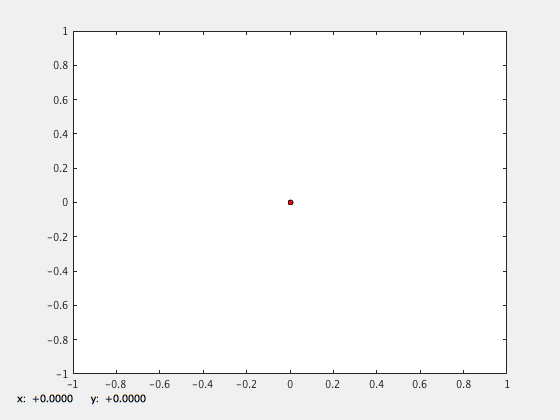

hx = uicontrol('Style', 'text', 'Units', 'char', 'Position', [1 1 11 1]);
hy = uicontrol('Style', 'text', 'Units', 'char', 'Position', [12 1 10 1]);
hx.String = sprintf('x: %+8.4f', x(1));
hy.String = sprintf('y: %+8.4f', x(2));

Axes limit checking.

xx = 1; yy = 1;       % The amount to increase/decrease the axes limits
axis([-xx xx -yy yy]) % Set initial axes limits

The animation loop. Use the handle `h` to the plot to replace `XData` and `YData` with new values. The loop continues until `UserData` becomes false.

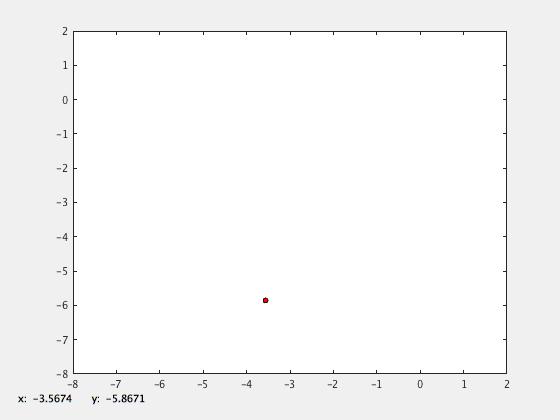

step = 0.1;
while hf.UserData
    theta = rand*2*pi; % Generate a random angle
    x = x + step*[cos(theta) sin(theta)]; % Update coordinates
    h.XData = x(1); h.YData = x(2); % Update plot
    
    % Print the coordinates of the point
    hx.String = sprintf('x: %+8.4f', x(1));
    hy.String = sprintf('y: %+8.4f', x(2));
    
    % Check axes limits. We can update XLim and YLim in place
    if x(1) < ha.XLim(1)
        ha.XLim(1) = ha.XLim(1) - xx;
    elseif x(1) > ha.XLim(2)
        ha.XLim(2) = ha.XLim(2) + xx;
    end
    
    if x(2) < ha.YLim(1)
        ha.YLim(1) = ha.YLim(1) - yy;
    elseif x(2) > ha.YLim(2)
        ha.YLim(2) = ha.YLim(2) + yy;
    end
    
    drawnow % Draw the new plot
end

Next we do the same using a `start/stop` button. See the callback function at the end of the script.

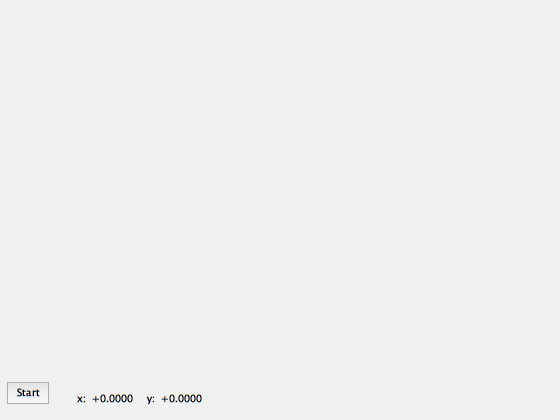

figure('Visible', 'on')
hx = uicontrol('Style', 'text', 'Units', 'char', 'Position', [10 1 10 1]);
hy = uicontrol('Style', 'text', 'Units', 'char', 'Position', [20 1 10 1]);
hx.String = sprintf('x: %+8.4f', 0);
hy.String = sprintf('y: %+8.4f', 0);
uicontrol('Style', 'pushbutton', 'Units', 'char', 'Position', [1 1 6 1.5],...
    'UserData', false, 'String', 'Start', 'Callback',...
    {@startbuttonCallback, hx, hy})

## Exercise 6

Open the video file for writing.

cobj = VideoWriter('contour', 'mpeg-4')

cobj =   VideoWriter

    General Properties:

       Filename:                 'contour.mp4'
       Path:                     '/Users/timoh/Documents/TeX Docs/SC/2018 Spring/S04/mfiles04'
       FileFormat:               'mp4'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'H.264'
       Quality:                  75

  Methods


open(cobj)

Generate the mesh for plotting

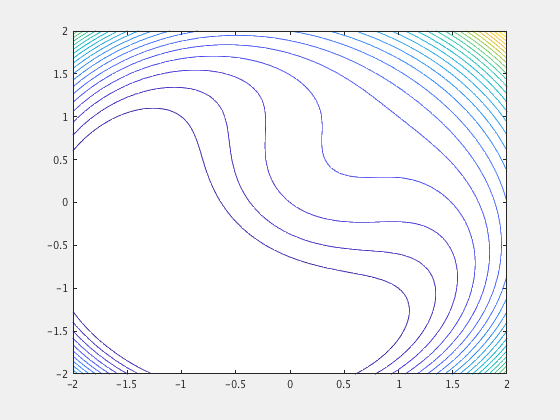

figure('Visible', 'on')

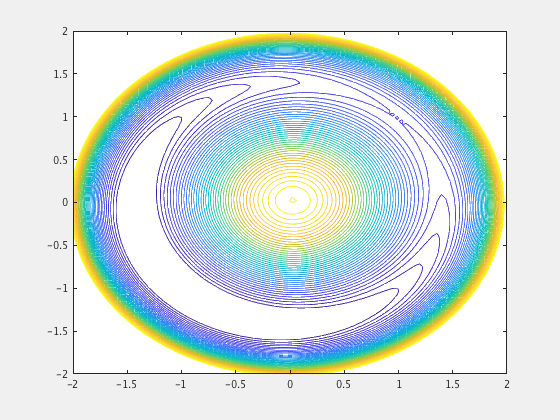

[X, Y] = meshgrid(linspace(-2, 2, 100));
% Plot the contours
for m = 0.5:0.05:10
    Z = X + Y + 0.5*m*(X.^2 + Y.^2 - 2).^2;
    contour(X, Y, Z, 0:0.5:20)
    frame = getframe;
    writeVideo(cobj, frame);
end

close(cobj)

function startbuttonCallback(hObject, ~, hx, hy) % Don't need the second argument
% A callback for the Start/Stop button.

if hObject.UserData
    % Animation is currently running. Setting UserData to false stops it.
    hObject.UserData = false;
else
    % Animation is not running, so we start it and change the button text to
    % 'Stop'.
    hObject.UserData = true;
    hObject.String = 'Stop';
    
    % Plot the initial point
    x = [0 0];
    h = plot(x(1), x(2), 'o', 'MarkerSize', 5,...
	'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'k');
    
    delta = 1;       % The amount to increase/decrease the axes limits
    axis([-1 1 -1 1]) % Set initial axes limits

    % The animation loop continues until UserData becomes false when the user
    % clicks the button.
    step = 0.1;
    ha = gca;
    while hObject.UserData
        theta = rand*2*pi; % Generate a random angle
        x = x + step*[cos(theta) sin(theta)]; % Update coordinates
        h.XData = x(1); h.YData = x(2); % Update plot
        
        % Print the coordinates of the point
        hx.String = sprintf('x: %+8.4f', x(1));
        hy.String = sprintf('y: %+8.4f', x(2));
        
        % Check axes limits.
        if x(1) < ha.XLim(1)
            ha.XLim(1) = ha.XLim(1) - delta;
        elseif x(1) > ha.XLim(2)
            ha.XLim(2) = ha.XLim(2) + delta;
        end
        
        if x(2) < ha.YLim(1)
            ha.YLim(1) = ha.YLim(1) - delta;
        elseif x(2) > ha.YLim(2)
            ha.YLim(2) = ha.YLim(2) + delta;
        end
        
        drawnow % Draw the new plot
    end
    hObject.String = 'Start'; % Restore the button text to 'Start'
end
end